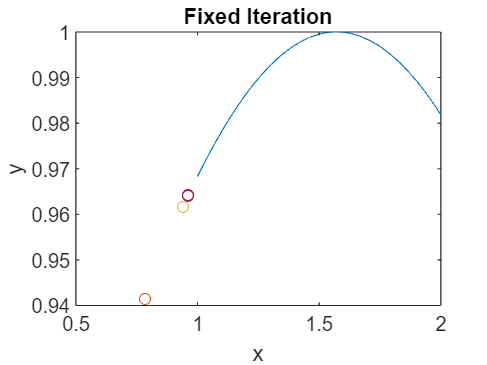

P = 0.9643

After 5 iterations


a = 1; b = 2;
p0 =pi/4 ;
i = 1;
N = 300;
TOL = 1e-4;
x = linspace(1,2,100);
figure
plot(x, g(x)); hold on
plot(p0,g(p0), 'Marker', 'o', 'MarkerSize',5)
title("Fixed Iteration")
xlabel('x')
ylabel('y')


while i<= N
    P = g(p0);
    plot(P,g(P), 'Marker', 'o', 'MarkerSize',5)
    if abs(P- p0) < TOL
        P
        output = sprintf("After %i iterations", i);
        disp(output)
        break;
    end
    i = i + 1;
    p0 = P;
    if i == N + 1
        output = sprintf('The method failed after N iterations, N = %n',N);
        disp(output)
    end
end

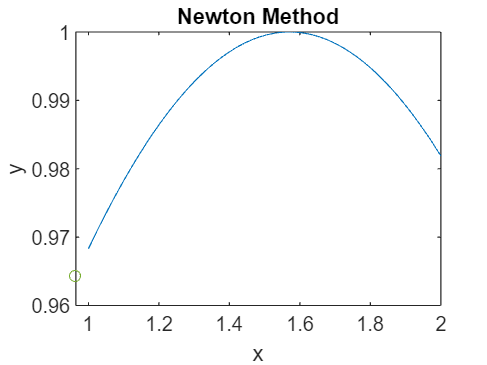

p = 0.9643

After 3 iterations


 

figure
plot(x, g(x)); hold on
plot(p0,g(p0), 'Marker', 'o', 'MarkerSize',5)
title("Newton Method")
xlabel('x')
ylabel('y')
i = 1;
p0 = 1;
while i <= N
    gfun = f(p0);
    gder = h(p0);
    p = p0 - gfun./gder; plot(p,g(p),'Marker','o','MarkerSize',5)
    if abs(p-p0)< TOL
        p
        output = sprintf("After %i iterations", i);
        disp(output)
        break
    end
    i = i +1;
   
    p0 = p;
end

if i == N + 1
    output = sprintf('The medthod failed after N0 iterations, N0 = %i', N);
    disp(output)

end







function y = g(x)
y =   0.2*sin(x)+0.8;
end
function y = f(x)
y =x -0.8 - 0.2*sin(x);
end
function y = h(x)
y = 1 - 0.2*cos(x);
end